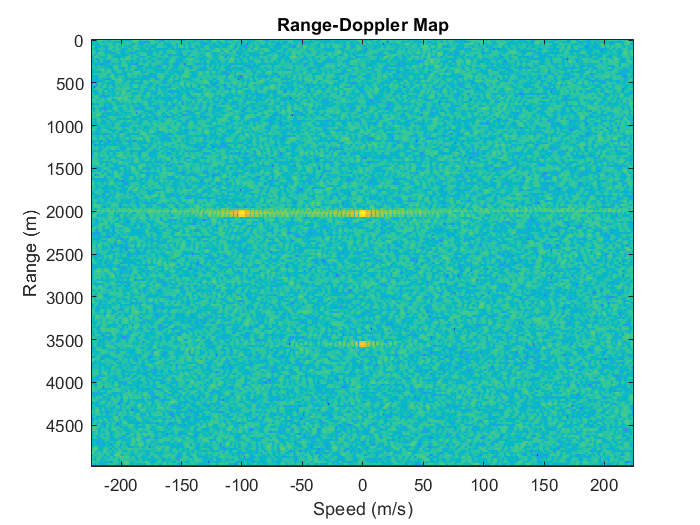

% Cargar data de senal
load RangeDopplerExampleData;

% Crear un objeto de respuesta (Doppler)
response = phased.RangeDopplerResponse('DopplerFFTLengthSource','Property', ...
'DopplerFFTLength',RangeDopplerEx_MF_NFFTDOP, ...
'SampleRate',RangeDopplerEx_MF_Fs,'DopplerOutput','Speed', ...
'OperatingFrequency',RangeDopplerEx_MF_Fc);

% Calcular el rango de respuesta
[resp,rng_grid,dop_grid] = response(RangeDopplerEx_MF_X, ...
RangeDopplerEx_MF_Coeff);

% Graficar el rango 
figure(1)
imagesc(dop_grid,rng_grid,mag2db(abs(resp)));
xlabel('Speed (m/s)');
ylabel('Range (m)');
title('Range-Doppler Map');

% Crear un objeto de respuesta (Doppler)
hrdresp = phased.RangeDopplerResponse(...
'RangeMethod','FFT',...
'PropagationSpeed',RangeDopplerEx_Dechirp_PropSpeed,...
'SampleRate',RangeDopplerEx_Dechirp_Fs,...
'DechirpInput',true,...
'SweepSlope',RangeDopplerEx_Dechirp_SweepSlope); 

% Calcular el rango de respuesta
[resp,rng_grid,dop_grid] = step(hrdresp,...
RangeDopplerEx_Dechirp_X,RangeDopplerEx_Dechirp_Xref);

% Estimacion del rango a traves de maximos
[x_temp,idx_temp] = max(abs(resp));
[~,dop_idx] = max(x_temp);
rng_idx = idx_temp(dop_idx);
dop_est = dop_grid(dop_idx); % Doppler shift
rng_est = rng_grid(rng_idx); % Distance of target

% Display de resultados
formatSpec1 = "The doppler shift is %d Hz";
A1 = dop_est;
str1 = sprintf(formatSpec1,A1);
disp(str1)

The doppler shift is -7.128906e+02 Hz



formatSpec2 = "The distance of target is %d meters";
A2 = rng_est;
str2 = sprintf(formatSpec2,A2);
disp(str2)

The distance of target is 2250 meters


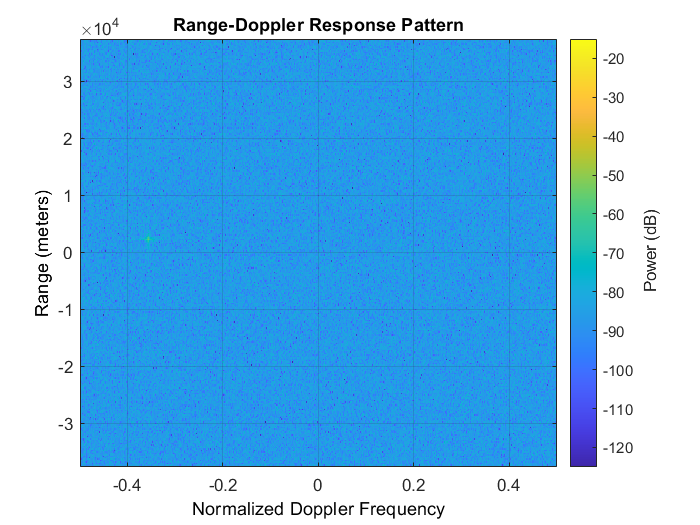

% Crear un objeto de respuesta (Doppler)
hrdresp = phased.RangeDopplerResponse(...
'RangeMethod','FFT',...
'PropagationSpeed',RangeDopplerEx_Dechirp_PropSpeed,...
'SampleRate',RangeDopplerEx_Dechirp_Fs,...
'DechirpInput',true,...
'SweepSlope',RangeDopplerEx_Dechirp_SweepSlope);

% Graficar el rango de respuesta
figure(2)
plotResponse(hrdresp,...
RangeDopplerEx_Dechirp_X,RangeDopplerEx_Dechirp_Xref,...
'Unit','db','NormalizeDoppler',true)

% Condiciones iniciales
antenna = phased.IsotropicAntennaElement(...
'FrequencyRange',[5e9 15e9]);
transmitter = phased.Transmitter('Gain',20,'InUseOutputPort',true);
fc = 10e9;
target = phased.RadarTarget('Model','Nonfluctuating',...
'MeanRCS',1,'OperatingFrequency',fc);
txloc = [0;0;0]; % location for the antena, global origina
tgtloc = [5000;5000;10]; % location for the target
antennaplatform = phased.Platform('InitialPosition',txloc);
targetplatform = phased.Platform('InitialPosition',tgtloc);
[tgtrng,tgtang] = rangeangle(targetplatform.InitialPosition,...
antennaplatform.InitialPosition);

% Plot del rango de la respuesta
waveform = phased.RectangularWaveform('PulseWidth',2e-6,'OutputFormat','Pulses','PRF',10000,'NumPulses',1);
c = physconst('LightSpeed');
maxrange = c/(2*waveform.PRF);
SNR = npwgnthresh(1e-6,1,'noncoherent');
lambda = c/target.OperatingFrequency;
maxrange = c/(2*waveform.PRF);
tau = waveform.PulseWidth;
Ts = 290;
dbterm = db2pow(SNR - 2*transmitter.Gain);
Pt = (4*pi)^3*physconst('Boltzmann')*Ts/tau/target.MeanRCS/lambda^2*maxrange^4*dbterm;
